%%Segmentering af sudukoplade felter
clear; close all; clc
x = 'sudoku_input.png' %Zoom PDF 132%
sudokuBW = imread(x);
%sudukoBW=imresize(sudukoBW,1.5);
figure
imshow(sudokuBW)
actuelSize = size(sudokuBW);
originalSize = 450;
scaleFaktor = originalSize/actuelSize(1);
sudokuBW = imresize(sudokuBW,scaleFaktor);

   data = sudokuBW;
    imChange1 = rgb2gray(data);
    %imChange2 = medfilt2(imChange1, [1 1]);
    imChange3 = imbinarize(imChange1,0.18); %0.18 normalt (0.07 ved grøn)  (im2bw)
    imChange4 = bwareaopen(imChange3,200); %300
    bw = bwlabel(imChange4, 8);
    felt_data = regionprops(bw, 'BoundingBox', 'Centroid');
    
    figure
    imshow(bw);
    imagesc(data);
    
    hold on
    
    pos_data = []
    for object = 1:length(felt_data)
        bb = felt_data(object).BoundingBox;
        bc = felt_data(object).Centroid;
        
        pos_data = [bc];
        rectangle('Position',bb,'EdgeColor','g','LineWidth',0.8)
        plot(bc(1),bc(2), '-black+')
       
        textX=text(bc(1)-20,bc(2)+5, strcat('X:', num2str(round(bc(1)))));
        textY=text(bc(1)-20,bc(2)+15, strcat('Y:', num2str(round(bc(2)))));
        set(textX, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
        set(textY, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
    end
    hold off
 pos_data
 format short G
 felt_data

x_center =[];
y_center =[];
 for i = 0:size(felt_data)-1
     find_x=felt_data(1+i).Centroid(1);
     x_center = [x_center,find_x];
     find_y=felt_data(1+i).Centroid(2);
     y_center = [y_center,find_y];
 end
 
 x_center
y_center

%koordinater på boksene - X og Y på venstre top hjørne og højre nedre
%hjørne 

x_box_topLeft=[];
y_box_topLeft=[];

x_box_botRight=[];
y_box_botRight=[];
for i = 0:size(felt_data)-1
     find_x1=felt_data(1+i).BoundingBox(1);
     x_box_topLeft = [x_box_topLeft,find_x1];
     
     find_y1=felt_data(1+i).BoundingBox(2);
     y_box_topLeft = [y_box_topLeft,find_y1];
     
     
     
     find_x2=felt_data(1+i).BoundingBox(3);
     x_box_botRight = [x_box_botRight,(find_x2+find_x1)];
     
     find_y2=felt_data(1+i).BoundingBox(4);
     y_box_botRight = [y_box_botRight,(find_y2+find_y1)]; 
     
     
 end
 x_box_topLeft
 
 y_box_topLeft
 
 x_box_botRight
y_box_botRight

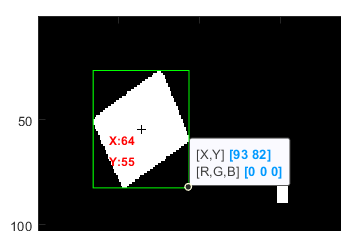

34.5+59 = modsatte hjørne kordinat X

26.5+56 = modsatte hjørnekordinat Y

  
    %opdater figur ved hvert loop:
    %drawnow;

% Her laver vi vores korrelations profiler :)
boundaries=bwboundaries(imChange4);

Image = {}
for i = 1:81
    [xmin, ymin]=min(boundaries{i,1});
    [xmax, ymax]=max(boundaries{i,1});
    Image{end+1,1}=imChange1(xmin(1,1):xmax(1,1),xmin(1,2):xmax(1,2)); 
end
Image


grid = correlationImage(Image);
grid 

grid_solved = sudoku(grid);
grid_solved

maxValue
x = cell2mat(maxValue)
y = 41
z = 50
subplot(2,1,1)
stem([0 1 2 3 4 5 6 7 8 9],x(y:z), 'b')
xlabel('Number')
ylabel('Max korrelations værdi for hvert')
title('Stemplot over max værdierne for hvert tal')
subplot(2,1,2)
imshow(Image{z/10,1});

bweuler(Image{z/10,1},8)